# Using Simulink to Generate Fault Data

This example shows how to use a Simulink modFaultCodeel to generate fault and healthy data. The fault and healthy data is used to develop a condition monitoring algorithm. The example uses a transmission system and models a gear tooth fault, a sensor drift fault and shaft wear fault. 

## Transmission System Model

The transmission casing model uses Simscape Driveline blocks to model a simple transmission system. The transmission system consists of a torque drive, drive shaft, clutch,  and high and low gears connected to an output shaft. 

mdl = 'pdmTransmissionCasing';
open_system(mdl)

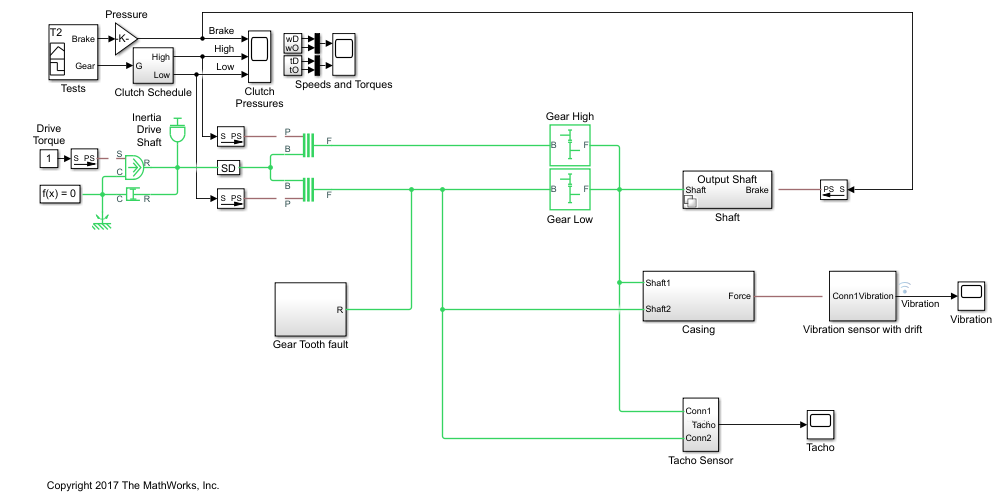

The transmission system includes a vibration sensor that is monitoring casing vibrations. The casing model translates the shaft angular displacement to a linear displacement on the casing. The casing is modelled as a mass spring damper system and the vibration (casing acceleration) is measured from the casing. 

open_system([mdl '/Casing'])


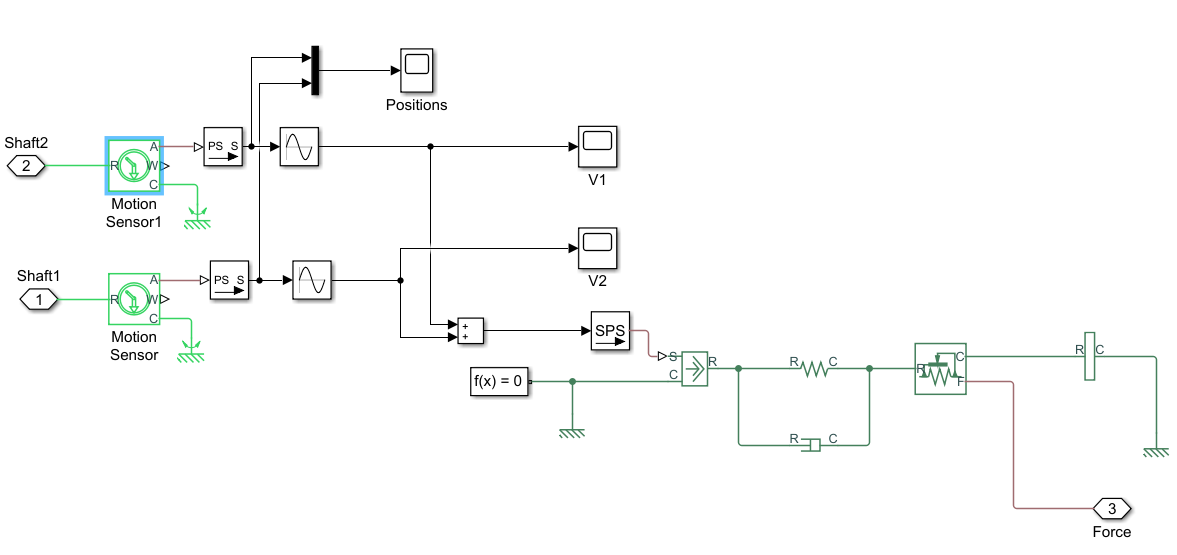

## Fault Modelling

The transmission system includes fault models for vibration sensor drift, gear tooth fault, and shaft wear. The sensor drift fault is easily modeled by introducing an offset in the sensor model. The offset is controlled by the model variable `SDrift`, note that `SDrift=0` implies no sensor fault. 

Pełzanie (dryft) (ang. drift) obejmuje zmiany sygnału wyj-

ściowego przetwornika, które mają miejsce nawet wtedy, gdy

nie występują żadne zmiany wielkości mierzonej lub warun-

ków środowiskowych. Jedyną zmienną podczas pomiaru

dryftu jest upływ czasu [127].

open_system([mdl '/Vibration sensor with drift'])

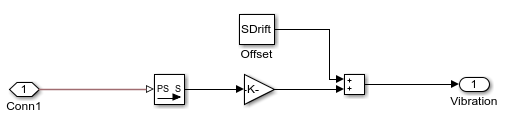

Zuycie walu

The shaft wear fault is modeled by a variant subsystem. In this case the subsystem variants change the shaft damping but the variant subsystem could be used to completely change the shaft model implementation. The selected variant is controlled by the model variable` ShaftWear`, note that` ShaftWear=0` implies no shaft fault.

open_system([mdl '/Shaft'])

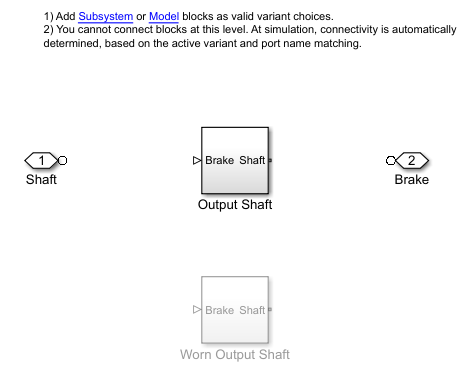

open_system([mdl,'/Shaft/Output Shaft'])

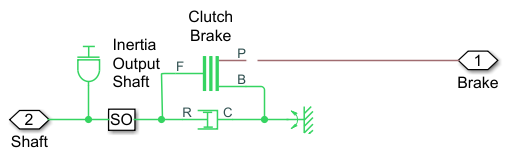

Uszkodzenie zeba przekadni

The gear tooth fault is modelled by injecting a disturbance torque at a fixed position in the rotation of the drive shaft. The shaft position is measured in radians and when the shaft position is within a small window around 0 a disturbance force is applied to the shaft. The  magnitude of the disturbance is controlled by the model variable `ToothFaultGain`, note that `ToothFaultGain=0` implies no gear tooth fault.

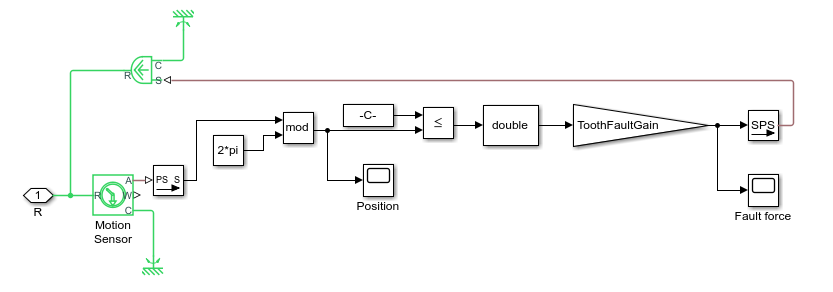

## Simulating Fault and Healthy Data

The transmission model is configured with variables that control the presence and severity of the three different fault types, sensor drift, gear tooth, and shaft wear.  By varying the model variables, `SDrift`, `ToothFaultGain`, and `ShaftWear`, you can create vibration data for the different fault types. Use an array of `Simulink.SimulationInput` objects to define a number of different simulation scenarios. For example, choose an array of values for each of the model variables and then use the `ndgrid` function to create a `Simulink.SimulationInput` for each combination of model variable values. 

toothFaultArray = -2:2/10:0; % Tooth fault gain values
sensorDriftArray = -1:0.5:1; % Sensor drift offset values
shaftWearArray = [0 -1];       % Variants available for drive shaft conditions

% Create an n-dimensional array with combinations of all values
[toothFaultValues,sensorDriftValues,shaftWearValues] = ...
    ndgrid(toothFaultArray,sensorDriftArray,shaftWearArray);

for ct = numel(toothFaultValues):-1:1
    % Create a Simulink.SimulationInput for each combination of values
    siminput = Simulink.SimulationInput(mdl);
    
    % Modify model parameters
    siminput = setVariable(siminput,'ToothFaultGain',toothFaultValues(ct));
    siminput = setVariable(siminput,'SDrift',sensorDriftValues(ct));
    siminput = setVariable(siminput,'ShaftWear',shaftWearValues(ct));
    
    % Collect the simulation input in an array
    gridSimulationInput(ct) = siminput;
end

Similarly create combinations of random values for each model variable. Make sure to include the `0` value so that there are combinations where only subsets of the three fault types are represented.

rng('default'); % Reset random seed for reproducibility
toothFaultArray = [0 -rand(1,6)];    % Tooth fault gain values
sensorDriftArray = [0 randn(1,6)/8]; % Sensor drift offset values
shaftWearArray = [0 -1];               % Variants available for drive shaft conditions

%Create an n-dimensional array with combinations of all values
[toothFaultValues,sensorDriftValues,shaftWearValues] = ...
    ndgrid(toothFaultArray,sensorDriftArray,shaftWearArray);

for ct=numel(toothFaultValues):-1:1
    % Create a Simulink.SimulationInput for each combination of values
    siminput = Simulink.SimulationInput(mdl);
    
    % Modify model parameters
    siminput = setVariable(siminput,'ToothFaultGain',toothFaultValues(ct));
    siminput = setVariable(siminput,'SDrift',sensorDriftValues(ct));
    siminput = setVariable(siminput,'ShaftWear',shaftWearValues(ct));
    
    % Collect the simulation input in an array
    randomSimulationInput(ct) = siminput;
end

With the array of `Simulink.SimulationInput` objects defined use the `generateSimulationEnsemble` function to run the simulations. The `generateSimulationEnsemble` function configures the model to save logged data to file, use the timetable format for signal logging and store the `Simulink.SimulationInput` objects in the saved file. The `generateSimulationEnsemble` function returns a status flag indicating whether the simulation completed successfully. 

The code above created 110 simulation inputs from the gridded variable values and `98 `simulation inputs from the random variable values giving 208 total simulations. Running these 208 simulations in parallel can take as much as two hours or more on a standard desktop and generates around 10GB of data. An option to only run the first 10 simulations is provided for convenience. 

% Run the simulations and create an ensemble to manage the simulation results
if ~exist(fullfile(pwd,'Data'),'dir')
    mkdir(fullfile(pwd,'Data')) % Create directory to store results
end
runAll = true;
if runAll
   [ok,e] = generateSimulationEnsemble([gridSimulationInput, randomSimulationInput], ...
        fullfile(pwd,'Data'),'UseParallel', true);
else
    [ok,e] = generateSimulationEnsemble(gridSimulationInput(1:10), fullfile(pwd,'Data')); %#ok<*UNRCH>
end

[04-Jan-2022 16:06:29] Checking for availability of parallel pool...
[04-Jan-2022 16:06:29] Starting Simulink on parallel workers...
[04-Jan-2022 16:06:30] Configuring simulation cache folder on parallel workers...
[04-Jan-2022 16:06:31] Transferring base workspace variables used in the model to parallel workers...
[04-Jan-2022 16:06:31] Loading model on parallel workers...
[04-Jan-2022 16:07:02] Running simulations...
[04-Jan-2022 16:07:48] Completed 1 of 208 simulation runs
[04-Jan-2022 16:07:49] Completed 2 of 208 simulation runs
[04-Jan-2022 16:07:52] Completed 3 of 208 simulation runs
[04-Jan-2022 16:07:53] Completed 4 of 208 simulation runs
[04-Jan-2022 16:07:53] Completed 5 of 208 simulation runs
[04-Jan-2022 16:07:54] Completed 6 of 208 simulation runs
[04-Jan-2022 16:08:04] Completed 7 of 208 simulation runs
[04-Jan-2022 16:08:05] Completed 8 of 208 simulation runs
[04-Jan-2022 16:08:06] Completed 9 of 208 simulation runs
[04-Jan-2022 16:08:06] Completed 10 of 208 simulation r

The `generateSimulationEnsemble` ran and logged the simulation results. Create a simulation ensemble to process and analyze the simulation results using the `simulationEnsembleDatastore` command.

ens = simulationEnsembleDatastore(fullfile(pwd,'Data'));

## Processing the Simulation Results

The `simulationEnsembleDatastore` command created an ensemble object that points to the simulation results. Use the ensemble object to prepare and analyze the data in each member of the ensemble. The ensemble object lists the data variables in the ensemble and by default all the variables are selected for reading.

ens

ens =   simulationEnsembleDatastore with properties:

           DataVariables: [6×1 string]
    IndependentVariables: [0×0 string]
      ConditionVariables: [0×0 string]
       SelectedVariables: [6×1 string]
                ReadSize: 1
              NumMembers: 208
          LastMemberRead: [0×0 string]
                   Files: [208×1 string]


ens.SelectedVariables

ans = 6×1 string array
    "SimulationInput"
    "SimulationMetadata"
    "Tacho"
    "Vibration"
    "xFinal"
    "xout"


For analysis only read the `Vibration` and `Tacho` signals and the `Simulink.SimulationInput`. The `Simulink.SimulationInput `has the model variable values used for simulation and is used to create fault labels for the ensemble members. Use the ensemble `read` command to get the ensemble member data.

ens.SelectedVariables = ["Vibration" "Tacho" "SimulationInput"];
data = read(ens)

data = 1×3 table
        Vibration              Tacho                 SimulationInput        
    _________________    _________________    ______________________________

    {486×1 timetable}    {486×1 timetable}    {1×1 Simulink.SimulationInput}


Extract the vibration signal from the returned data and plot it.

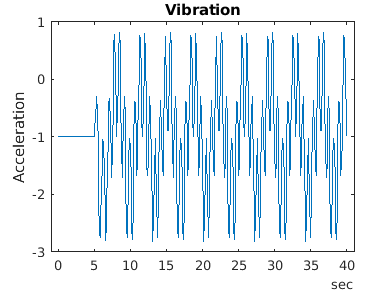

vibration = data.Vibration{1};
plot(vibration.Time,vibration.Data)
title('Vibration')
ylabel('Acceleration')

The first 10 seconds of the simulation contains data where the transmission system is starting up; for analysis discard this data.

idx = vibration.Time >= seconds(10);
vibration = vibration(idx,:);
vibration.Time = vibration.Time - vibration.Time(1);


The `Tacho` signal contains pulses for the rotations of the drive and load shafts but analysis, and specifically time synchronous averaging, requires the times of shaft rotations. The following code discards the first 10 seconds of the `Tacho` data and finds the shaft rotation times in `tachoPulses`.

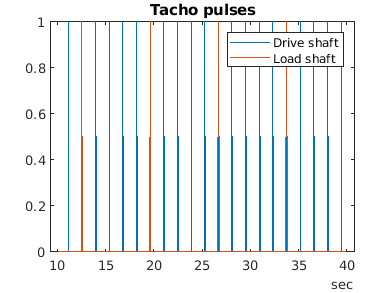

tacho = data.Tacho{1};
idx = tacho.Time >= seconds(10);
tacho = tacho(idx,:);
plot(tacho.Time,tacho.Data)
title('Tacho pulses')
legend('Drive shaft','Load shaft') % Load shaft rotates more slowly than drive shaft

idx = diff(tacho.Data(:,2)) > 0.5;
tachoPulses = tacho.Time(find(idx)+1)-tacho.Time(1)

tachoPulses = 4×1 duration array
   2.4507 sec
   9.5238 sec
   16.597 sec
    23.67 sec


The `Simulink.SimulationInput.Variables` property contains the values of the fault parameters used for the simulation, these values allow us to create fault labels for each ensemble member.

vars = data.SimulationInput{1}.Variables;
idx = strcmp({vars.Name},'SDrift');
if any(idx)
    sF = abs(vars(idx).Value) > 0.01; % Small drift values are not faults
else
    sF = false;
end
idx = strcmp({vars.Name},'ShaftWear');
if any(idx)
    sV = vars(idx).Value < 0;
else
    sV = false;
end
if any(idx)
    idx = strcmp({vars.Name},'ToothFaultGain');
    sT = abs(vars(idx).Value) < 0.1; % Small tooth fault values are not faults
else
    sT = false
end
faultCode = sF + 2*sV + 4*sT; % A fault code to capture different fault conditions

The processed vibration and tacho signals and the fault labels are added to the ensemble to be used later.

sdata = table({vibration},{tachoPulses},sF,sV,sT,faultCode, ...
    'VariableNames',{'Vibration','TachoPulses','SensorDrift','ShaftWear','ToothFault','FaultCode'})  

sdata = 1×6 table
        Vibration         TachoPulses      SensorDrift    ShaftWear    ToothFault    FaultCode
    _________________    ______________    ___________    _________    __________    _________

    {362×1 timetable}    {4×1 duration}       true          false        false           1    


ens.DataVariables = [ens.DataVariables; "TachoPulses"];

The ensemble `ConditionVariables` property can be used to identify the variables in the ensemble that contain condition or fault label data. Set the property to contain the newly created fault labels.

ens.ConditionVariables = ["SensorDrift","ShaftWear","ToothFault","FaultCode"];

The code above was used to process one member of the ensemble. To process all the ensemble members the code above was converted to the function `prepareData `and using the ensemble `hasdata` command a loop is used to apply `prepareData` to all the ensemble members. The ensemble members can be processed in parallel by partitioning the ensemble and processing the ensemble partitions in parallel.

reset(ens)
runLocal = false;
if runLocal
    % Process each member in the ensemble
    while hasdata(ens)
        data = read(ens);
        addData = prepareData(data);
        writeToLastMemberRead(ens,addData)
    end
else
    % Split the ensemble into partitions and process each partition in parallel
    n = numpartitions(ens,gcp);
    parfor ct = 1:n
        subens = partition(ens,n,ct);
        while hasdata(subens)
            data = read(subens);
            addData = prepareData(data);
            writeToLastMemberRead(subens,addData)
        end
    end    
end

Plot the vibration signal of every 10th member of the ensemble using the `hasdata` and `read` commands to extract the vibration signal.

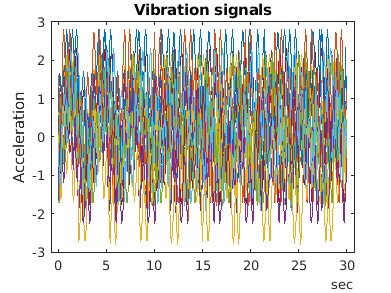

reset(ens)
ens.SelectedVariables = "Vibration";
figure, 
ct = 1;
while hasdata(ens)
    data = read(ens);
    if mod(ct,10) == 0
        vibration = data.Vibration{1};
        plot(vibration.Time,vibration.Data)
        hold on
    end
    ct = ct + 1;
end
hold off
title('Vibration signals')
ylabel('Acceleration')

## Analyzing the Simulation Data

Now that the data has been cleaned and pre-processed the data is ready for extracting features to determine the features to use to classify the different faults types. First configure the ensemble so that it only returns the processed data.

ens.SelectedVariables = ["Vibration","TachoPulses"];

For each member in the ensemble compute a number of time and spectrum based features. These include signal statistics such as signal mean, variance, peak to peak, non-linear signal characteristics such as approximate entropy and Lyapunov exponent, and spectral features such as the peak frequency of the time synchronous average of the vibration signal, and the power of the time synchronous average envelope signal. The `analyzeData` function contains a full list of the extracted features. By way of example consider computing the spectrum of the time synchronous averaged vibration signal.

reset(ens)
data = read(ens)

data = 1×2 table
        Vibration         TachoPulses  
    _________________    ______________

    {362×1 timetable}    {4×1 duration}


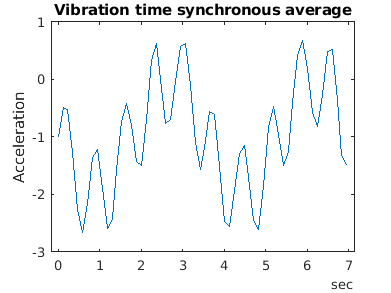

vibration = data.Vibration{1};

% Interpolate the Vibration signal onto periodic time base suitable for fft analysis
np = 2^floor(log(height(vibration))/log(2));
dt = vibration.Time(end)/(np-1);
tv = 0:dt:vibration.Time(end);
y = retime(vibration,tv,'linear');

% Compute the time synchronous average of the vibration signal
tp = seconds(data.TachoPulses{1});
vibrationTSA = tsa(y,tp);
figure
plot(vibrationTSA.ttTime,vibrationTSA.tsa)
title('Vibration time synchronous average')
ylabel('Acceleration')

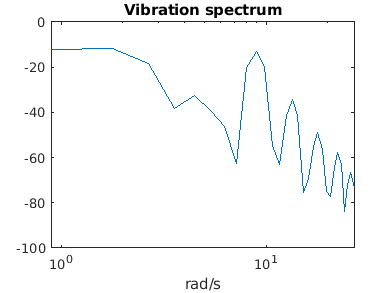

% Compute the spectrum of the time synchronous average
np = numel(vibrationTSA);
f = fft(vibrationTSA.tsa.*hamming(np))/np;
frTSA = f(1:floor(np/2)+1);            % TSA frequency response
wTSA = (0:np/2)/np*(2*pi/seconds(dt)); % TSA spectrum frequencies
mTSA = abs(frTSA);                     % TSA spectrum magnitudes
figure
semilogx(wTSA,20*log10(mTSA))
title('Vibration spectrum')
xlabel('rad/s')

The frequency that corresponds to the peak magnitude could turn out to be a feature that is useful for classifying the different fault types. The code below computes the features mentioned above for all the ensemble members (running this analysis can take up to an hour on a standard desktop. Optional code to run the analysis in parallel using the ensemble `partition` command is provided.) The names of the features are added to the ensemble data variables property before calling writeToLastMemberRead to add the computed features to each ensemble member.

reset(ens)
ens.DataVariables = [ens.DataVariables; ...
    "SigMean";"SigMedian";"SigRMS";"SigVar";"SigPeak";"SigPeak2Peak";"SigSkewness"; ...
    "SigKurtosis";"SigCrestFactor";"SigMAD";"SigRangeCumSum";"SigCorrDimension";"SigApproxEntropy"; ...
    "SigLyapExponent";"PeakFreq";"HighFreqPower";"EnvPower";"PeakSpecKurtosis"];
if runLocal
    while hasdata(ens)
        data = read(ens);
        addData = analyzeData(data);
        writeToLastMemberRead(ens,addData);
    end
else
    % Split the ensemble into partitions and analyze each partition in parallel
    n = numpartitions(ens,gcp);
    parfor ct = 1:n
        subens = partition(ens,n,ct);
        while hasdata(subens)
            data = read(subens);
            addData = analyzeData(data);
            writeToLastMemberRead(subens,addData)
        end
    end
end

> In signal.internal.skurtosis.computeKurtogram (line 35)
In kurtogram (line 108)
In analyzeData (line 114)
In parallel_function>make_general_channel/channel_general (line 852)
In remoteParallelFunction (line 67)
> In signal.internal.skurtosis.computeKurtogram (line 35)
In kurtogram (line 108)
In analyzeData (line 114)
In parallel_function>make_general_channel/channel_general (line 852)
In remoteParallelFunction (line 67)
> In signal.internal.skurtosis.computeKurtogram (line 35)
In kurtogram (line 108)
In analyzeData (line 114)
In parallel_function>make_general_channel/channel_general (line 852

## Selecting Features for Fault Classification

The features computed above are used to build a classifier to classify the different fault conditions. First configure the ensemble to read only the derived features and the fault labels.

featureVariables = analyzeData('GetFeatureNames');
ens.DataVariables = [ens.DataVariables; featureVariables];
ens.SelectedVariables = [featureVariables; ens.ConditionVariables];
reset(ens)

Gather the feature data for all the ensemble members into one table.

featureData = gather(tall(ens)) %tall - create tall table

Evaluating tall expression using the Parallel Pool 'local':
- Pass 1 of 1: 0% complete
Evaluation 0% complete

- Pass 1 of 1: Completed in 29 sec
Evaluation completed in 30 sec


featureData = 208×22 table
     SigMean      SigMedian     SigRMS     SigVar     SigPeak    SigPeak2Peak    SigSkewness    SigKurtosis    SigCrestFactor    SigMAD     SigRangeCumSum    SigCorrDimension    SigApproxEntropy    SigLyapExponent    PeakFreq    HighFreqPower     EnvPower     PeakSpecKurtosis    SensorDrift    ShaftWear    ToothFault    FaultCode
    _________    ___________    _______    _______    _______    ____________    ___________    ___________    ____________

Consider the sensor drift fault. Use the `fscnca` command with all the features computed above as predictors and the sensor drift fault label (a true false value) as the response. The `fscnca` command returns weights for each feature and features with higher weights have higher importance in predicting the response.  For the sensor drift fault the weights indicate that two features are significant predictors (the signal cumulative sum range and the peak frequency of  the spectral kurtosis)  and the remaining features have little impact. 

idxResponse = strcmp(featureData.Properties.VariableNames,'SensorDrift');
idxLastFeature = find(idxResponse)-1; % Index of last feature to use as a potential predictor
featureAnalysis = fscnca(featureData{:,1:idxLastFeature},featureData.SensorDrift); 
%fscnca learns the feature weights by using a diagonal adaptation of neighborhood component 
% analysis (NCA) with regularization.
featureAnalysis.FeatureWeights

ans =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


idxSelectedFeature = featureAnalysis.FeatureWeights > 0.1;
classifySD = [featureData(:,idxSelectedFeature), featureData(:,idxResponse)]

classifySD = 208×3 table
    SigRangeCumSum    PeakSpecKurtosis    SensorDrift
    ______________    ________________    ___________

        369.26             2.6642            true    
        387.23             3.7263            true    
         354.3              2.664            true    
        366.05             3.7303            true    
        390.18             3.7214            true    
        390.21             3.7229            true    
        407.24              3.724            true    
        419.86             3.5481            true    
        418.28             3.5453            true    
        417.86             3.5427            true    
        372.86              3.731            true    
        374.45             3.7262            true    
         392.5             1.0634            true    
        375.63             1.0633            true    
        

A grouped histogram of the cumulative sum range gives us insight into why this feature is a significant predictor for the sensor drift fault.

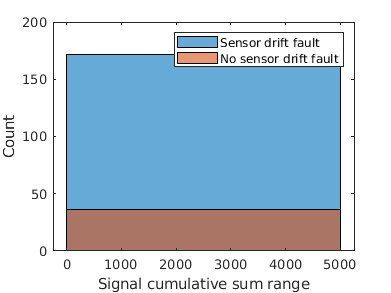

figure
histogram(classifySD.SigRangeCumSum(classifySD.SensorDrift),'BinWidth',5e3)
xlabel('Signal cumulative sum range')
ylabel('Count')
hold on
histogram(classifySD.SigRangeCumSum(~classifySD.SensorDrift),'BinWidth',5e3)
hold off
legend('Sensor drift fault','No sensor drift fault')

The histogram plot shows that the signal cumulative sum range is a good featured for detecting sensor drift faults though an additional feature is probably needed as there may be false positives when the signal cumulative sum range is below 0.5 if just the signal cumulative sum range is used to classify sensor drift.

Consider the shaft wear fault. In this case the `fscnca` function indicates that there are 3 features that are significant predictors for the fault (the signal Lyapunov exponent, peak frequency, and the peak frequency in the spectral kurtosis), choose these to classify the shaft wear fault. 

idxResponse = strcmp(featureData.Properties.VariableNames,'ShaftWear');
featureAnalysis = fscnca(featureData{:,1:idxLastFeature},featureData.ShaftWear);
featureAnalysis.FeatureWeights

ans =     0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


idxSelectedFeature = featureAnalysis.FeatureWeights > 0.1;
classifySW = [featureData(:,idxSelectedFeature), featureData(:,idxResponse)]

classifySW = 208×4 table
    SigCorrDimension    SigLyapExponent    PeakSpecKurtosis    ShaftWear
    ________________    _______________    ________________    _________

         1.9553              2.5738             2.6642           false  
        0.75634            0.015909             3.7263           false  
         1.8501              3.2588              2.664           true   
         1.5767               3.441             3.7303           true   
         2.2884              2.5603             3.7214           true   
         2.2629            0.028972             3.7229           true   
         2.2544              2.2722              3.724           true   
         2.1035             0.74353             3.5481           true   
         2.0452              0.8147             3.5453           true   
        0.95968             0.50503

The grouped histogram for the signal Lyapunov exponent shows why that feature alone is not a good predictor.

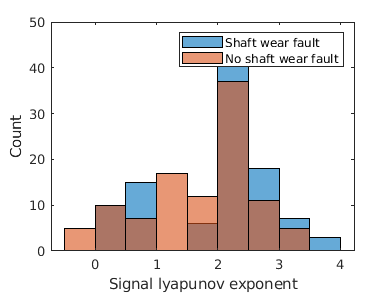

figure
histogram(classifySW.SigLyapExponent(classifySW.ShaftWear))
xlabel('Signal lyapunov exponent')
ylabel('Count')
hold on
histogram(classifySW.SigLyapExponent(~classifySW.ShaftWear))
hold off
legend('Shaft wear fault','No shaft wear fault')

The shaft wear feature selection indicates multiple features are needed to classify the shaft wear fault, the grouped histogram confirms this as the most significant feature (in this case the Lyapunov exponent) has a similar distribution for both faulty and fault free scenarios indicating that more features are needed to correctly classify this fault. 

Finally consider the tooth fault, the `fscnca` function indicates that there are 3 features primary that are significant predictors for the fault (the signal cumulative sum range, the signal Lyapunov exponent and the peak frequency in the spectral kurtosis). Choosing those 3 features to classify the tooth fault results in a classifier that has poor performance. Instead, use the 6 most important features.

idxResponse = strcmp(featureData.Properties.VariableNames,'ToothFault');
featureAnalysis = fscnca(featureData{:,1:idxLastFeature},featureData.ToothFault); 
[~,idxSelectedFeature] = sort(featureAnalysis.FeatureWeights);
classifyTF = [featureData(:,idxSelectedFeature(end-5:end)), featureData(:,idxResponse)]

classifyTF = 208×7 table
    PeakFreq    SigApproxEntropy     SigMean     SigLyapExponent    PeakSpecKurtosis    SigRangeCumSum    ToothFault
    ________    ________________    _________    _______________    ________________    ______________    __________

         0          0.58614           -1.0252         2.5738             2.6642             369.26          false   
         0          0.29927           -1.0146       0.015909             3.7263             387.23          false   
         0          0.58303           0.97477         3.2588              2.664              354.3          false   
         0          0.54379           0.96634          3.441             3.7303             366.05          false   
         0          0.47608       

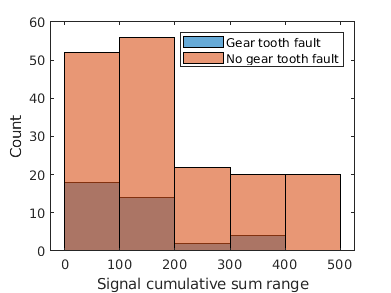

figure
histogram(classifyTF.SigRangeCumSum(classifyTF.ToothFault))
xlabel('Signal cumulative sum range')
ylabel('Count')
hold on
histogram(classifyTF.SigRangeCumSum(~classifyTF.ToothFault))
hold off
legend('Gear tooth fault','No gear tooth fault')

Using the above results a polynomial svm to classify gear tooth faults. Split the feature table into members that are used for training and members for testing and validation.  Use the training members to create a svm classifier using the `fitcsvm` command.

rng('default') % For reproducibility
cvp = cvpartition(size(classifyTF,1),'KFold',5); % Randomly partition the data for training and validation 
classifierTF = fitcsvm(...
    classifyTF(cvp.training(1),1:end-1), ...%Sample Data
    classifyTF(cvp.training(1),end), ...%Response
    'KernelFunction','polynomial', ...
    'PolynomialOrder',2, ...
    'KernelScale','auto', ...
    'BoxConstraint',1, ...
    'Standardize',true, ...
    'ClassNames',[false; true]);

Use the classifier to classify the test points using the `predict` command and check the performance of the predictions using a confusion matrix.

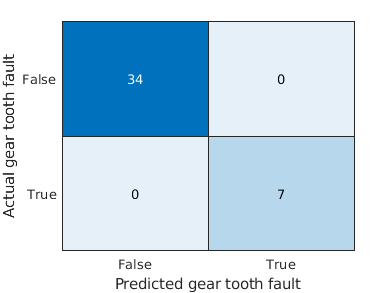

% Use the classifier on the test validation data to evaluate performance
actualValue = classifyTF{cvp.test(1),end};
predictedValue = predict(classifierTF, classifyTF(cvp.test(1),1:end-1));

% Check performance by computing and plotting the confusion matrix
confdata = confusionmat(actualValue,predictedValue);
h = heatmap(confdata, ...
    'YLabel', 'Actual gear tooth fault', ...
    'YDisplayLabels', {'False','True'}, ...
    'XLabel', 'Predicted gear tooth fault', ...
    'XDisplayLabels', {'False','True'}, ...
    'ColorbarVisible','off');   

The confusion matrix indicates that the classifier correctly classifies all non-fault conditions but incorrectly classifies one expected fault condition as not being a fault. Increasing the number of features used in the classifier can help improve the performance further. 

## Summary

This example walked through the workflow for generating fault data from Simulink, using a simulation ensemble to clean up the simulation data and extract features. The extracted features were then used to build classifiers for the different fault types.

*Copyright 2017-2018 The MathWorks, Inc.*